#  Relatório de Atividade - MOAB

*Débora Nunes Pinto de Oliveira*

*Prof. Antonio Marcus, Análise e Projeto de Sistemas de Controle 21.1*

*19 de Maio de 2021*

Esse documento tem por objetivo descrever a dinâmica de uma bola sobre um prato cuja angulação é controlada. Esse sistema é nomeado MOAB. Nesse trabalho, serão analisados o modelo dinâmico e as entradas de atuação sobre a pose do prato para que a bola percorra uma trajetória pré-definida. 

## Fundamentação teórica

O sistema de balanceamento de uma bola sobre um prato estudado nesse trabalho está ilustrado na Figura 1**. **No caso em estudo, o prato pode ser inclinado em duas direções perpendiculares ($\vec{x}
$ e $\vec{y}$) por meio do acionamento de três motores elétricos. Esses motores estão distribuído nos vértices de um triângulo equilátero, conforme ilustrado na Figura 2. A velocidade de rotação e angulação desses motores pode ser controlada para estabilizar a bola em um ponto específico do prato ou para navegar a bola sobre uma trajetória pré-definida. 

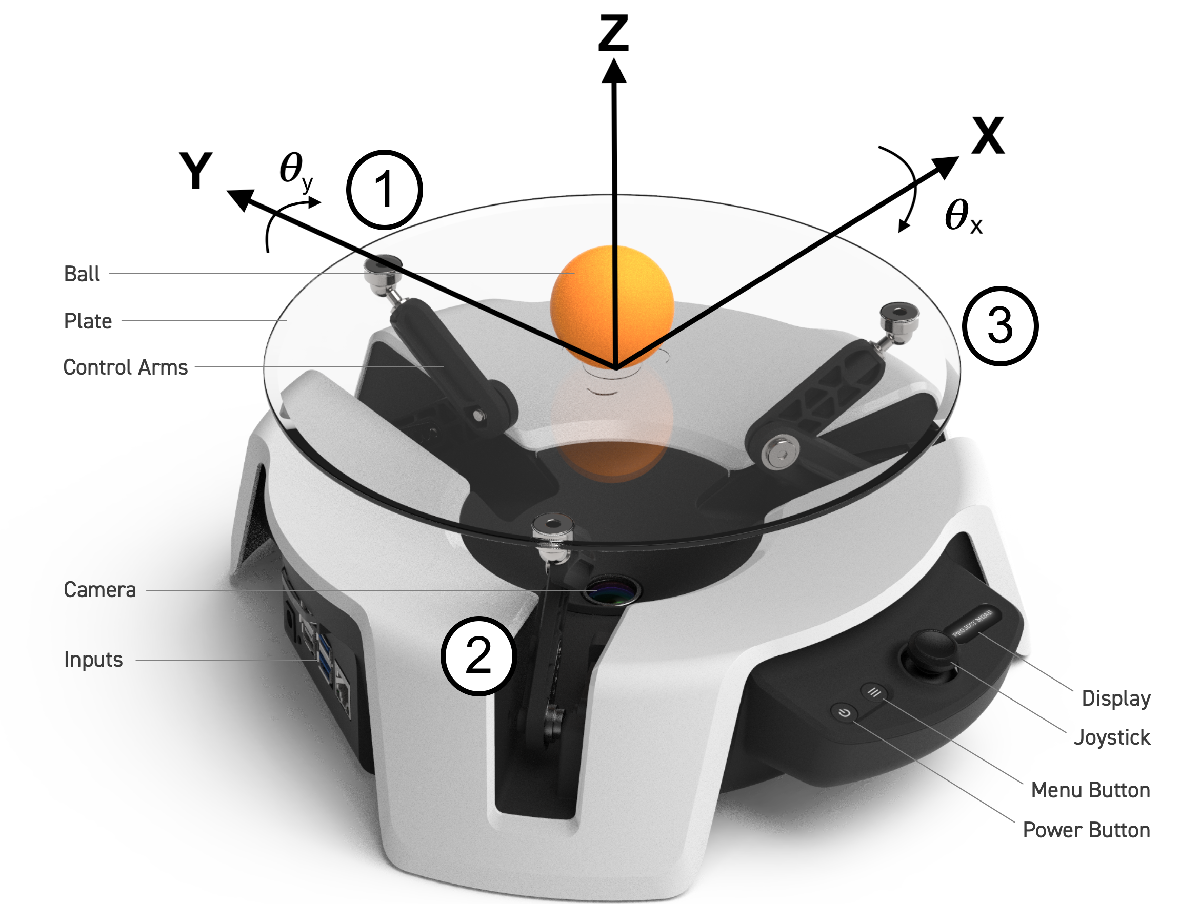

***Figura 1: ****Sistema da bola sobre um prato cuja angulação *$\theta_y$* e *$\theta_x$* é controlável. (Fonte: *[1])

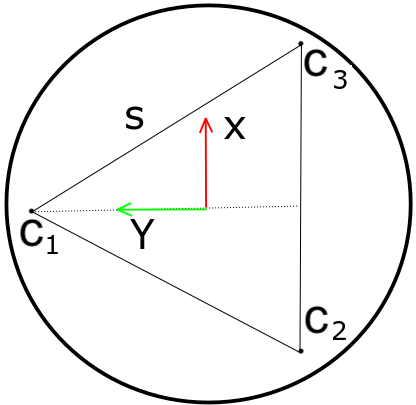

***Figura 2: ****Visão superior do prato. (Fonte: *[1])

O MOAB possui quatro graus de liberdade: dois graus de liberdade provenientes da inclinação do prato e dois graus referentes ao movimento da bola sobre o prato. Além disso, é importante destacar que a relação entre a posição atual da bola e a variação da inclinação do prato é não-linear. Para simplificar o modelo em estudo, são consideradas as seguintes premissas:

- A bola nunca perde contato com a superfície do prato.

- Não há deslizamento entre a bola e o prato.

- Forças de atrito são desprezíveis.

A estimativa do modelo será realizada pela formulação de Lagrange, uma vez que, em relação ao modelo cinemático newtoniano, é mais fácil tratar as mudanças de sistemas de coordenadas. 

### Modelo simulado

O Lagrangiano de um sistema é descrito por:


$$\mathcal{L}=T-V$$


para $T$ a energia cinética e $V$ a energia potencial do processo. A energia cinética do sistema é composta pela energia translacional da bola em relação à origem do prato, energia rotacional da bola em relação ao seu centro de massa, energia translacional do prato e energia rotacional da bola em relação à origem do prato. Como a origem do prato é o ponto pivotante, a energia translacional do prato é nula. Qualquer movimento não intencional do centro do prato em relação a sua origem será considerado desprezível.

A posição da bola em relação ao sistema inercial do prato pode ser escrita como:


$$\vec{r}=x\hat{i}+y\hat{j}+(-x\sin\theta_y+y\sin\theta_x)\hat{k}$$


Diferenciando a posição da bola em relação ao tempo, tem-se:


$$\dot{\vec{r}}=\dot{x}\hat{i}+\dot{y}\hat{i}+(-\dot{x}\sin\theta_y-x\dot{\theta_y}\cos\theta_y+\dot{y}\sin\theta_x+y\dot{\theta_x}\cos\theta_x)$$


Considerando que o ponto de equilíbrio é para $\theta_y$ e $\theta_x$ aproximadamente nulo, considera-se, pela expansão em série de Taylor, que $\cos\theta=1$ e $\sin\theta=0$. Dessa forma, a derivada da posição em relação ao tempo é reescrita como:


$$\dot{\vec{r}}=\dot{x}\hat{i}+\dot{y}\hat{i}+(-x\dot{\theta_y}+y\dot{\theta_x})$$


Por sua vez, A energia cinética pode ser expressa por:


$$T_{T} = \frac{1}{2}m_b|\dot{r}|^2 = \frac{1}{2}m_b\big[\dot{x}^2+\dot{y}^2+(-
x\dot{\theta_y}+y\dot{\theta_x})^2\big]$$


para $m_b$ a massa da bola. 

Como a bola não se separa da superfície do prato, a velocidade em relação ao prato é nula. Sendo assim, a velocidade rotacional da bola pode ser escrita como $\omega_b = v_b/r_b$ para $\vec{v_b}=\dot{x}\hat{i}+\dot{y}\hat{j}$ a delovidade da bola em relação ao prato e $r_b$ o raio da bola. Logo, a energia rotacional da bola ao redor do seu centro de gravidade é definida como:


$$T_{R} = \frac{1}{2}J_b\omega_b^2 = \frac{1}{2}J_b\frac{(\dot{x}^2+\dot{y}^2)}{r_b^{2}}$$


para $J_b$ o momento de inércia da bola. Por sua vez, a energia rotacional do sistema bola-prato em relação ao sistema de coordenadas inercial é dada por:


$$T_r = \frac{1}{2}J_b(\dot{\theta}_y^2+\dot{\theta}_x^2)+\frac{1}{2}J_{px}\dot{\theta}_x^2+\frac{1}{2}J_{py}\dot{\theta}_y^2$$


para $J_{px}$ e $J_{py}$ os momentos de inércia do prato em relação aos eixos $\vec{x}$ e $\vec{y}$, respectivamente. Por fim, a energia potencial da bola com o sistema em equilíbrio é dada por:


$$V=m_bg(-x\sin\theta_y+y\sin\theta_x)$$


Logo, tem-se que o Lagrangiano do sistema é $\mathcal L = T_T+T_R+T_r-V$, tal que:


$$\mathcal{L}=\frac{(\dot{x}^2+\dot{y}^2)(m_b+J_br_b^{-2})+m_b(x\dot{\theta}_y-y\dot{\theta}_x)^2+J_b(\dot{\theta_y}^2+\dot{\theta_x}^2)+J_{px}\dot{\theta}_x^2+J_{py}\dot{\theta}_y^2}{2}-m_bg(-x\sin\theta_y+y\sin\theta_x)$$


A equação de Lagrange-Euler descreve que:


$$\frac{d}{dt}\Bigg(\frac{\delta\mathcal{L}}{\delta\dot{q}_i}\Bigg)-\frac{\delta\mathcal{L}}{\delta q_i}=Q_i$$


para $q_i$ as coordenadas do sistema de coordenadas inercial no mundo e $Q_i$ as forças sobre o sistema. Para $\dot{q}_i=\dot{x}$ e $q_i=\dot{y}$ tem-se

$\frac{\delta\mathcal{L}}{\delta\dot{x}} = (m_b+J_br_b^{-2})\dot{x}$ e $\frac{\delta\mathcal{L}}{\delta\dot{y}} = (m_b+J_br_b^{-2})\dot{y}$

$\frac{\delta\mathcal{L}}{\delta x} =m_bg\sin\theta_y+m_b\dot{\theta}_y(x\dot{\theta}_y-y\dot{\theta}_x)$ e $\frac{\delta\mathcal{L}}{\delta y} =-m_bg\sin\theta_x+m_b\dot{\theta}_x(y\dot{\theta}_x+x\dot{\theta}_y)$

Derivando $\frac{\delta\mathcal{L}}{\delta{\dot{q_i}}}$ em relação ao tempo para $\dot{q}_i=\dot{x}$ e $q_i=\dot{y}$ t, tem-se:

$\frac{d}{dt}\bigg(\frac{\delta\mathcal{L}}{\delta\dot{x}}\bigg)= (m_b+J_br_b^{-2})\ddot{x}$ e $\frac{d}{dt}\bigg(\frac{\delta\mathcal{L}}{\delta\dot{y}}\bigg) = (m_b+J_br_b^{-2})\ddot{y}$

Como não há forças externas sobre o sistema, tem-se que $F_x=F_y=0$. Logo, é evidente que $Q_i=0$, para $q_i=y$ e $q_i=x$. Sendo assim, a equação de Euler-Lagrange para cada eixo é escrita para o modelo do MOAB como:


$$\frac{d}{dt}\bigg(\frac{\delta\mathcal{L}}{\delta\dot{x}}\bigg)-\frac{\delta\mathcal{L}}{\delta x}  =  (m_b+J_br_b^{-2})\ddot{x}-m_bg\sin\theta_y-m_b\dot{\theta}_y(x\dot{\theta}_y-y\dot{\theta}_x)=0$$



$$\frac{d}{dt}\bigg(\frac{\delta\mathcal{L}}{\delta\dot{y}}\bigg)  - \frac{\delta\mathcal{L}}{\delta y}  =  (m_b+J_br_b^{-2})\ddot{y} -m_bg\sin\theta_x+m_b\dot{\theta}_x(y\dot{\theta}_x+x\dot{\theta}_y)=0$$


O momento de inércia para uma casca esférica é dada como $J_b=\frac{2}{5}m_b\frac{(r_2)^5 - (r_1)^5}{(r_2)^3 - (r_1)^3}$ para $r_1$ e $r_2$ o raio interno e externo, respectivamente. Isolando a segunda derivada das variáveis $x$ e $y$ em relação ao tempo, obtém-se:

$\ddot{x}=\frac{m_b(x\dot{\theta}_y^2-y\dot{\theta}_x\dot{\theta}_y+g\sin\theta_y)}{(m_b+J_br_b^{-2})}$ e $\ddot{y}=\frac{m_b(y\dot{\theta}_x^2+x\dot{\theta}_y\dot{\theta}_x-g\sin\theta_x)}{(m_b+J_br_b^{-2})}$

No que lhe concerne, o controle sobre a angulação do prato $\theta_x$ e $\theta_y$ é realizada pelo acionamento de três motores. 

### Variáveis de atuação

Na Figura 3 está ilustrado um corte do MOAB ortogonal ao eixo do Motor 1 (M1). Considerando que $d$ é a distância do vértice superior do triangulo equilátero em relação ao seu baricentro, é evidente que $d=s/\sqrt{3}$, para $s$ a lateral do triângulo equilátero ilustrado na Figura 2.

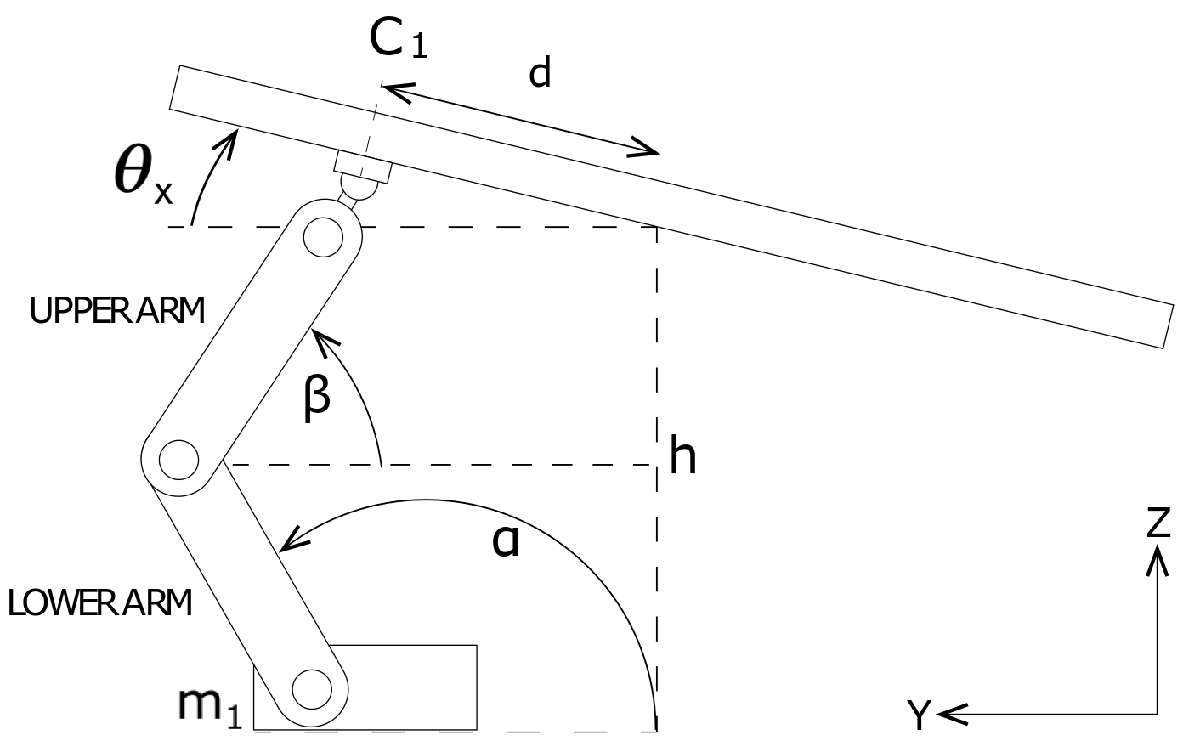

***Figura 3: ****Corte ortogonal ao eixo *$\vec{x}$*. (Fonte: *[1])

Para o ponto $C_1$ de apoio do prato sobre o braço conectado ao motor 1, tem-se que a altura $z_{C1}$ em relação à base do motor é:


$$z_{C1}=h+\frac{s}{\sqrt{3}}\sin\theta_x$$


para $h$ a altura do baricentro do prato em relação ao solo. Analogamente, na Figura 4 está um corte do MOAB ortogonal aos eixos do Motor 2 (M2) e Motor 3 (M3). 

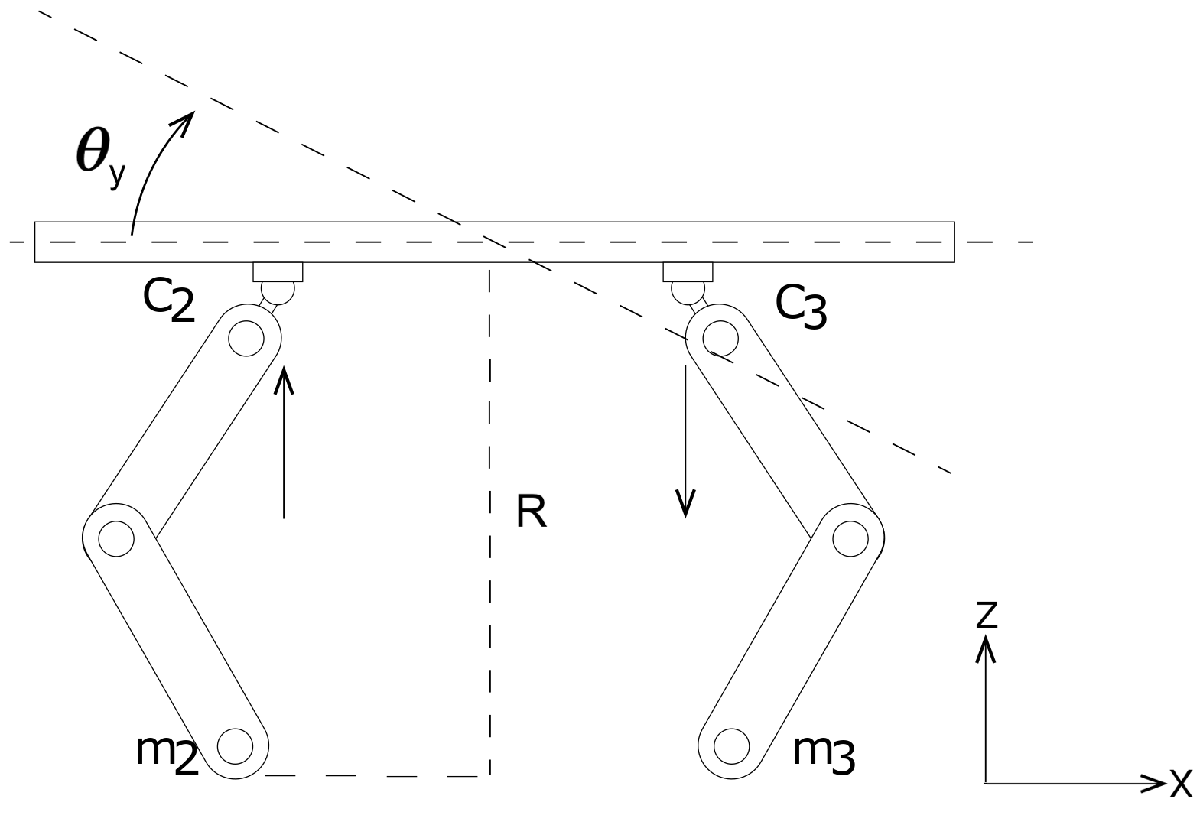

***Figura 4: ****Corte ortogonal ao eixo *$\vec{y}$*. (Fonte: *[1])

Observando a Figura 2 e comparando-a com a Figura 4, é possível afirmar que os motores M2 e M3 distam $s/2$ da mediana do triângulo equilátero de lado $s$. Sendo assim, a altura dos pontos de apoio do prato nos braços 2 ($z_{C2}$) e 3 ($z_{C3}$) são:

$z_{C2}=R+\frac{s}{\sqrt{3}}\sin\theta_y$ e $z_{C3}=R-\frac{s}{\sqrt{3}}\sin\theta_y$

para $R$ a altura do ponto medial da aresta entre os vértices M2 e M3. Essa altura é dada de modo semelhante à $z_{C1}$, visto que dista $2s/\sqrt{3}$ do baricentro. Sendo assim, tem-se que:


$$R = h-\frac{2s}{\sqrt{3}}\sin\theta_x$$


Considerando que as juntas entre os braços e o prato são completamente esféricas, cada ponto de apoio $C_i$ está alinhado verticalmente com o respectivo motor $M_i$. Dessa forma, os ângulos $\alpha_1$ e $\beta_1$ ilustrados na Figura 3 são equivalentes. Como o comprimento dos dois eixos do brço são iguais e representados pela variável $L$, é possível afimar que, para $h_\alpha = h_\beta = L\sin\alpha = L\sin\beta$:


$$z_{C1} = h_\alpha+h_\beta = 2L\sin\alpha_1$$


O ângulo $\alpha_1$ representa a angulação do motor M1. Sendo assim, a atuação sobre o sistema é formulada como:


$$\alpha_i = \arcsin{\bigg(\frac{z_{Ci}}{2L}\bigg)}$$


para $i=[1,2,3]$. Para evitar singularidades, deve-se manter $90^\circ<\alpha<145^\circ$. 

## Metodologia, experimentos e discussão

O modelo do MOAB descrito pelas equações diferenciais e a cinemática direta descrita pela relação de  e  conforme a altura das juntas  foram simuladas pela ferramenta Simulink. Para verificar a veracidade das equações formuladas para o modelo, foram simulados dois experimentos.

Primeiramente, o sistema foi escrito na ferramenta Simscape [1]. Em segundo lugar, as equações diferenciais de $x$ e $y$ foram representadas conforme um diagrama de blocos no Simulink. Em ambos os experimentos, a malha foi fechada conforme os valores de referência $\theta_x^\ast$ e $\theta_y^\ast$ ilustrados na Figura 5.

initializeMoab;

showing Mechanics Explorer


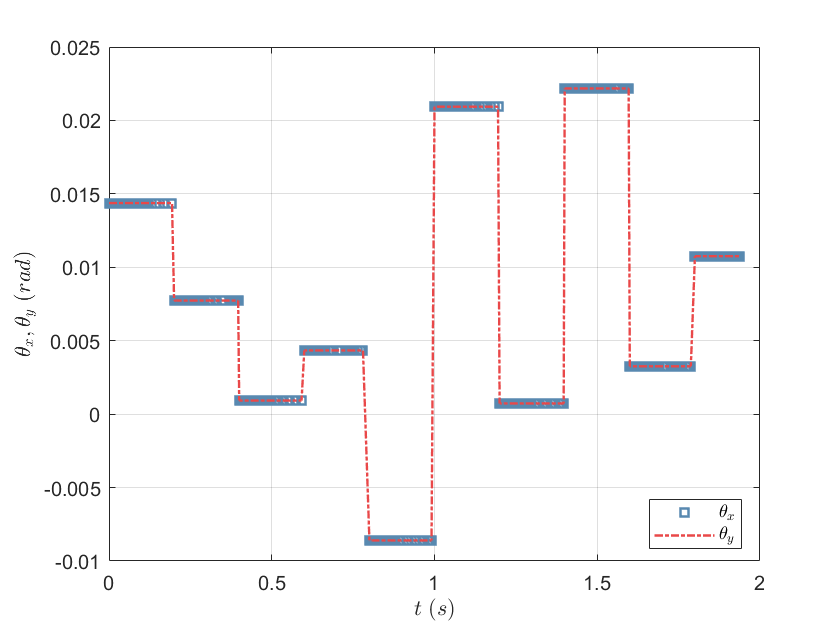

out = sim('MyMOAB.slx');
input

***Figura 5:**** Referência angular *$\theta_x^\ast$* e *$\theta_y^\ast$* para o modelo do MOAB.*

Por sua vez, os resultados da posição da bola $x$ e $y$ conforme os valores de entrada para $\theta_x^\ast$ e $\theta_y^\ast$ para ambos os experimentos está ilustrada na Figura 6.

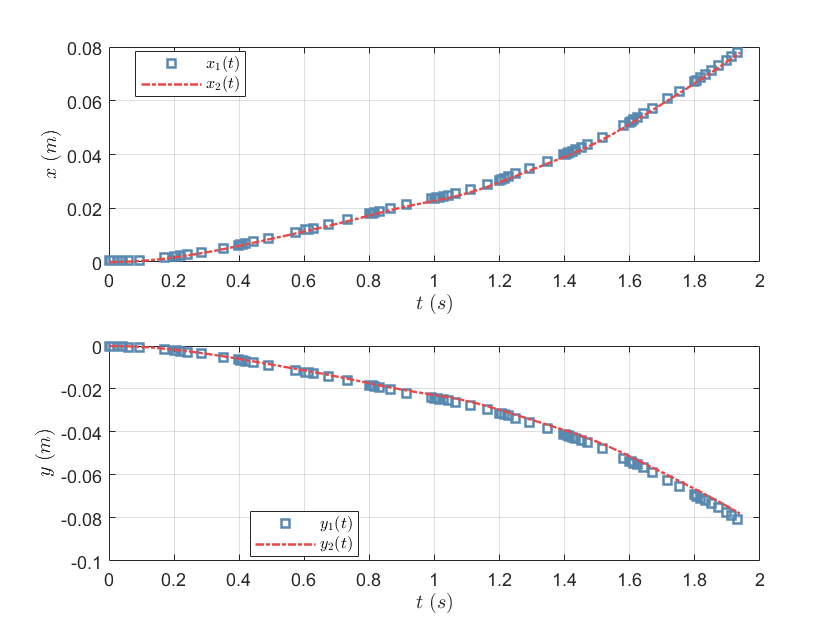

output

***Figura 6:**** Posição da bola *$(x,y)$* em relação ao sistema de coordenadas inercial para o experimento com o Simscape (1) e com o diagrama de blocos (2).*

Observando a Figura 6, é evidente que o modelo simulado no Simscape retorna valores menores em ambos os eixos em relação ao resultado do diagrama de blocos. Essa observação é justificada em razão do equacionamento diferencial representado no Experimento 2, o qual considera a premissa de atrito nulo. Por sua vez, o simulador Simscape considera um coeficiente de atrito estático e dinâmico não nulo, uma vez que o movimento da bola sobre o prato deriva da existência de uma força de atrito entre as superfícies. Sendo assim, é possível concluir que as perdas consideradas no modelo do Experimento 1 são desprezadas no Experimento 2.

## Referências bibliográficas

[1] A. SINGH. **Moab System Modeling and PID Controller Design**. 